Scientific Programming - TCGA Ovarian Cancer dataset

05 - Survival Models

- Prepare clinical data for Cox regression

clear;
clc;
close all;

load("results/cleaned_data.mat");

% Check available clinical variables
clinical_dfs.Properties.VariableNames'

ans = 21×1 cell array
    {'SAMPLE_ID'                      }
    {'PATIENT_ID'                     }
    {'TUMOR_STAGE_2009'               }
    {'GRADE'                          }
    {'TUMOR_RESIDUAL_DISEASE'         }
    {'ACGH_DATA'                      }
    {'MRNA_DATA'                      }
    {'SEQUENCED'                      }
    {'COMPLETE_DATA'                  }
    {'CANCER_TYPE'                    }
    {'CANCER_TYPE_DETAILED'           }
    {'ONCOTREE_CODE'                  }
    {'SAMPLE_TYPE'                    }
    {'SOMATIC_STATUS'                 }
    {'TMB_NONSYNONYMOUS'              }
    {'PRIMARY_THERAPY_OUTCOME_SUCCESS'}
    {'PLATINUM_STATUS'                }
    {'OS_STATUS'                      }
    {'OS_MONTHS'                      }
    {'DFS_STATUS'                     }
    {'DFS_MONTHS'                     }



if ~exist("figures", "dir")
    mkdir("figures");
end

Collapse stage into II, III and IV:

stage = string(clinical_dfs.TUMOR_STAGE_2009);

stageCollapsed = strings(size(stage));

stageCollapsed(ismember(stage, ...
    ["IIA","IIB","IIC"])) = "II";

stageCollapsed(ismember(stage, ...
    ["IIIA","IIIB","IIIC"])) = "III";

stageCollapsed(stage == "IV") = "IV";

stageCollapsed(stageCollapsed == "") = missing;

stageCollapsed = categorical(stageCollapsed);

countcats(stageCollapsed)

ans =     24
   313
    57


Some substages contained few patients, which would make separate Cox coefficient estimates unstable. Therefore, substages were collapsed into the broader Stage II, III and IV groups to increase the number of observations per category while preserving clinically interpretable disease stages.

Grade and residual disease:

%% Recode clinical missing values properly

gradeString = string(clinical_dfs.GRADE);
gradeString(gradeString == "NA") = missing;
grade = categorical(gradeString);

residualString = string(clinical_dfs.TUMOR_RESIDUAL_DISEASE);
residualString(residualString == "NA") = missing;
residual = categorical(residualString);

2. Identify patients with complete information:

%% Complete-case cohort

time = clinical_dfs.DFS_MONTHS;

eventStatus = string(clinical_dfs.DFS_STATUS);

% Event = recurrence/progression
event = contains(eventStatus, "Recurred", ...
    'IgnoreCase', true) | ...
    contains(eventStatus, "Progressed", ...
    'IgnoreCase', true);

completeCases = ...
    ~isnan(time) & ...
    ~ismissing(stageCollapsed) & ...
    ~ismissing(grade) & ...
    ~ismissing(residual);

fprintf("Patients available for clinical Cox model: %d\n", ...
    sum(completeCases));

Patients available for clinical Cox model: 346



fprintf("Events: %d\n", ...
    sum(event(completeCases)));

Events: 253



fprintf("Censored: %d\n", ...
    sum(~event(completeCases)));

Censored: 93


3. Encode clinical predictor

% Restrict to complete cases
time_cc = time(completeCases);
event_cc = event(completeCases);

stage_cc = stageCollapsed(completeCases);
grade_cc = grade(completeCases);
residual_cc = residual(completeCases);

% Check category order
categories(stage_cc)

ans = 3×1 cell array
    {'II' }
    {'III'}
    {'IV' }


categories(grade_cc)

ans = 2×1 cell array
    {'G2'}
    {'G3'}


categories(residual_cc)

ans = 4×1 cell array
    {'1-10 mm'               }
    {'11-20 mm'              }
    {'>20mm'                 }
    {'No Macroscopic disease'}


4. Create dummy variables for Cox regression

%% Stage dummies
% Reference = Stage II

stageIII = double(stage_cc == 'III');
stageIV  = double(stage_cc == 'IV');

%% Grade dummy
% Reference = G2

gradeG3 = double(grade_cc == 'G3');

%% Residual disease dummies
% Reference = No Macroscopic disease

residual_1_10 = double(residual_cc == '1-10 mm');
residual_11_20 = double(residual_cc == '11-20 mm');
residual_gt20 = double(residual_cc == '>20mm');

%% Combine predictors

Xclinical = [ ...
    stageIII, ...
    stageIV, ...
    gradeG3, ...
    residual_1_10, ...
    residual_11_20, ...
    residual_gt20 ...
    ];

size(Xclinical)

ans =    346     6


Dummy variables were used to represent the categorical predictors. Stage II, G2, and no macroscopic residual disease were chosen as reference categories because they represent the less advanced or more favorable category within each predictor, making the resulting hazard ratios straightforward to interpret.

5. Fit clinical Cox proportional hazards model

% MATLAB coxphfit uses censoring = 1 for censored observations
censoring = ~event_cc;

[b, logL, H, stats] = coxphfit( ...
    Xclinical, ...
    time_cc, ...
    'Censoring', censoring);

%% Hazard ratios and confidence intervals

hazardRatio = exp(b);

% 95% Wald confidence intervals.
% 1.96 is the approximate 97.5th percentile of the standard normal distribution.
CI_lower = exp(b - 1.96 * stats.se);
CI_upper = exp(b + 1.96 * stats.se);

predictorNames = { ...
    'Stage III vs II'; ...
    'Stage IV vs II'; ...
    'Grade G3 vs G2'; ...
    'Residual 1-10 mm vs none'; ...
    'Residual 11-20 mm vs none'; ...
    'Residual >20 mm vs none'};

coxResults = table( ...
    predictorNames, ...
    b, ...
    stats.se, ...
    hazardRatio, ...
    CI_lower, ...
    CI_upper, ...
    stats.p, ...
    'VariableNames', { ...
    'Predictor', ...
    'Beta', ...
    'SE', ...
    'HazardRatio', ...
    'CI_Lower', ...
    'CI_Upper', ...
    'PValue'});

disp(coxResults)

              Predictor               Beta        SE       HazardRatio    CI_Lower    CI_Upper     PValue  
    _____________________________    _______    _______    ___________    ________    ________    _________

    {'Stage III vs II'          }    0.50636    0.32188      1.6592       0.88292      3.1181       0.11568
    {'Stage IV vs II'           }    0.81994    0.35508      2.2704         1.132      4.5535      0.020932
    {'Grade G3 vs G2'           }    0.24894     0.1902      1.2827       0.88351      1.8622        0.1906
    {'Residual 1-10 mm vs none' }    0.51048    0.17272      1.6661        1.1876      2.3373     0.0031209
    {'Residual 11-20 mm vs none'}    0.63787    0.28817      1.8924        1.0758      3.3291      0.026863
    {

HR > 1 - higher hazard of recurrence/progression compared with reference group

HR < 1 - lower hazard

In the multivariable Cox model, Stage IV and residual disease of 1–10 mm or 11–20 mm were significantly associated with higher recurrence/progression hazard. Grade was not significantly associated with disease-free survival after adjustment for the other predictors. Residual disease showed the most consistent association across its categories.

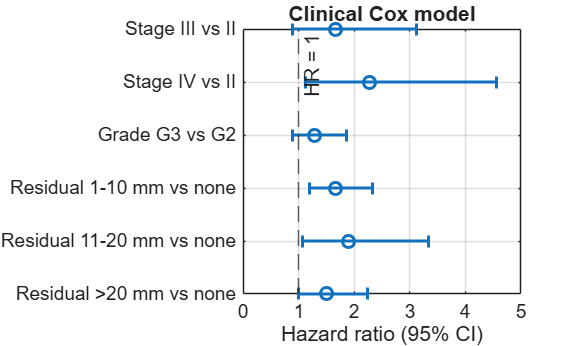

%% Forest plot for clinical Cox model

figure;

% Plot hazard ratios with 95% confidence intervals
errorbar( ...
    coxResults.HazardRatio, ...
    1:height(coxResults), ...
    coxResults.HazardRatio - coxResults.CI_Lower, ...
    coxResults.CI_Upper - coxResults.HazardRatio, ...
    'horizontal', ...
    'o', ...
    'LineWidth', 1.5);

hold on;

% Reference line: HR = 1 means no difference from reference group
xline(1, '--', 'HR = 1');

% Predictor labels
yticks(1:height(coxResults));
yticklabels(coxResults.Predictor);

% Put first predictor at the top
set(gca, 'YDir', 'reverse');

xlabel('Hazard ratio (95% CI)');
title('Clinical Cox model');

grid on;
hold off;

saveas(gcf, "figures/forestplot_clinicalcox.png");

6. Check proportional hazards assumption

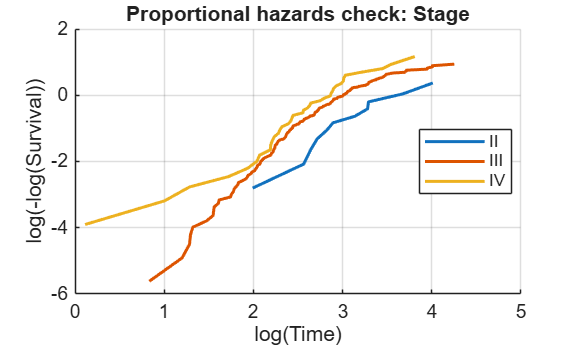

% Log-minus-log survival curves for stage

figure;
hold on;

stageGroups = categories(stage_cc);

for i = 1:numel(stageGroups)

    idx = stage_cc == stageGroups{i};

    % Kaplan-Meier estimate
    [S,tKM] = ecdf( ...
        time_cc(idx), ...
        'Censoring', censoring(idx), ...
        'Function','survivor');

    % Remove values that cannot be log-transformed
    valid = ...
        tKM > 0 & ...
        S > 0 & ...
        S < 1;

    plot( ...
        log(tKM(valid)), ...
        log(-log(S(valid))), ...
        'LineWidth',1.5);

end

xlabel('log(Time)');
ylabel('log(-log(Survival))');
title('Proportional hazards check: Stage');
legend(stageGroups, 'Location','best');
grid on;
hold off;

saveas(gcf, "figures/prophazards_stage.png");

The log-minus-log survival curves for tumor stage were broadly parallel, with some deviation at earlier times. No strong violation of the proportional hazards assumption was evident from visual inspection.

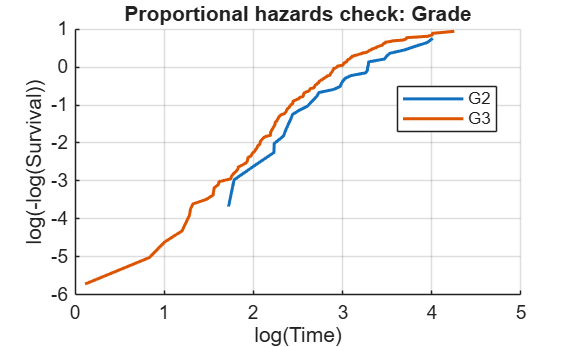

%% Proportional hazards check: Grade

figure;
hold on;

gradeGroups = categories(grade_cc);

for i = 1:numel(gradeGroups)

    idx = grade_cc == gradeGroups{i};

    [S,tKM] = ecdf( ...
        time_cc(idx), ...
        'Censoring', censoring(idx), ...
        'Function','survivor');

    valid = ...
        tKM > 0 & ...
        S > 0 & ...
        S < 1;

    plot( ...
        log(tKM(valid)), ...
        log(-log(S(valid))), ...
        'LineWidth',1.5);

end

xlabel('log(Time)');
ylabel('log(-log(Survival))');
title('Proportional hazards check: Grade');
legend(gradeGroups, 'Location','best');
grid on;
hold off;
saveas(gcf, "figures/prophazards_grade.png");

The log-minus-log survival curves for tumor grade were approximately parallel, suggesting that the proportional hazards assumption was reasonable for grade.

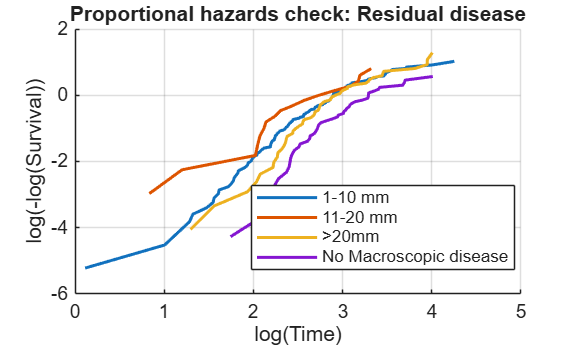

%% Proportional hazards check: Residual disease

figure;
hold on;

residualGroups = categories(residual_cc);

for i = 1:numel(residualGroups)

    idx = residual_cc == residualGroups{i};

    [S,tKM] = ecdf( ...
        time_cc(idx), ...
        'Censoring', censoring(idx), ...
        'Function','survivor');

    valid = ...
        tKM > 0 & ...
        S > 0 & ...
        S < 1;

    plot( ...
        log(tKM(valid)), ...
        log(-log(S(valid))), ...
        'LineWidth',1.5);

end

xlabel('log(Time)');
ylabel('log(-log(Survival))');
title('Proportional hazards check: Residual disease');
legend(residualGroups, 'Location','best');
grid on;
hold off;
saveas(gcf, "figures/prophazards_residualdisease.png");

The log-minus-log survival curves for residual disease were generally similar in shape, although some crossing and early-time deviations were present. No severe violation of the proportional hazards assumption was evident visually, but the assumption appears less clear than for grade. 

7. Apparent C-index of clinical Cox model

% Linear predictor from Cox model
riskScore = Xclinical * b;

concordant = 0;
comparable = 0;

n = numel(time_cc);

for i = 1:n-1
    for j = i+1:n

        % Patient i had an observed event before patient j
        if event_cc(i) && time_cc(i) < time_cc(j)

            comparable = comparable + 1;

            if riskScore(i) > riskScore(j)
                concordant = concordant + 1;

            elseif riskScore(i) == riskScore(j)
                concordant = concordant + 0.5;
            end

            % Patient j had an observed event before patient i
        elseif event_cc(j) && time_cc(j) < time_cc(i)

            comparable = comparable + 1;

            if riskScore(j) > riskScore(i)
                concordant = concordant + 1;

            elseif riskScore(j) == riskScore(i)
                concordant = concordant + 0.5;
            end

        end
    end
end

cIndex = concordant / comparable;

fprintf("Clinical Cox apparent C-index: %.3f\n", cIndex);

Clinical Cox apparent C-index: 0.603


fprintf("Comparable patient pairs: %d\n", comparable);

Comparable patient pairs: 41372


The clinical Cox model achieved an apparent C-index of 0.603 across 41,372 comparable patient pairs, indicating modest ability to rank patients by disease-free survival risk. Because this value was calculated on the same cohort used to fit the model, it likely overestimates performance on unseen patients.

8. 5-fold cross validated C-index for clinical Cox model

Five-fold cross-validation was chosen as a compromise between retaining a large training set and maintaining sufficiently sized test folds. With 346 patients, each test fold contains approximately 69 patients. The same five-fold structure was used consistently throughout the predictive analyses.

rng(1);

cvCox = cvpartition(event_cc, 'KFold', 5);

cvRiskScore = nan(size(time_cc));

for fold = 1:cvCox.NumTestSets

    trainIdx = training(cvCox, fold);
    testIdx  = test(cvCox, fold);

    Xtrain = Xclinical(trainIdx,:);
    Xtest  = Xclinical(testIdx,:);

    timeTrain = time_cc(trainIdx);
    censorTrain = ~event_cc(trainIdx);

    %% Fit Cox model on training fold only

    bFold = coxphfit( ...
        Xtrain, ...
        timeTrain, ...
        'Censoring', censorTrain);

    %% Predict risk for held-out patients

    cvRiskScore(testIdx) = Xtest * bFold;

end

%% Cross-validated C-index

concordant = 0;
comparable = 0;

n = numel(time_cc);

for i = 1:n-1
    for j = i+1:n

        % Patient i had an observed event before patient j
        if event_cc(i) && time_cc(i) < time_cc(j)

            comparable = comparable + 1;

            if cvRiskScore(i) > cvRiskScore(j)
                concordant = concordant + 1;

            elseif cvRiskScore(i) == cvRiskScore(j)
                concordant = concordant + 0.5;
            end

            % Patient j had an observed event before patient i
        elseif event_cc(j) && time_cc(j) < time_cc(i)

            comparable = comparable + 1;

            if cvRiskScore(j) > cvRiskScore(i)
                concordant = concordant + 1;

            elseif cvRiskScore(j) == cvRiskScore(i)
                concordant = concordant + 0.5;
            end

        end
    end
end

cvCIndex = concordant / comparable;

fprintf("Clinical Cox 5-fold CV C-index: %.3f\n", cvCIndex);

Clinical Cox 5-fold CV C-index: 0.576


fprintf("Comparable patient pairs: %d\n", comparable);

Comparable patient pairs: 41372


The clinical Cox model achieved a 5-fold cross-validated C-index of 0.576, compared with an apparent C-index of 0.603. This reduction indicates some optimism in the training-set estimate. Overall, the clinical variables provided modest discrimination of disease-free survival risk on unseen patients.

Clinical-only baseline: 5-fold CV C-index: 0.576

Clinical + expression Cox model

9. Sensitivity analysis: 5, 10 and 20 expression PCs

The models were evaluated with 5, 10 and 20 PCs as a sensitivity analysis across increasing levels of expression-model complexity. These values were not assumed to be optimal: 5 PCs provided a low-dimensional representation, 10 represented an intermediate model, and 20 tested whether retaining additional expression structure improved prediction. The aim was to assess dependence on model complexity rather than to search exhaustively for the best PC count.

rng(1);

% Expression data for the same complete-case patients
Xexpr = expression_dfs(:, completeCases)';

% Number of PCs to compare
nPC_values = [5 10 20];

cvCombined = cvpartition(event_cc, 'KFold', 5);

cvRiskCombined = nan(numel(time_cc), numel(nPC_values));

for fold = 1:cvCombined.NumTestSets

    trainIdx = training(cvCombined, fold);
    testIdx  = test(cvCombined, fold);

    %% Clinical data

    XclinicalTrain = Xclinical(trainIdx,:);
    XclinicalTest  = Xclinical(testIdx,:);

    %% Expression data

    XexprTrain = Xexpr(trainIdx,:);
    XexprTest  = Xexpr(testIdx,:);

    %% Variance filtering using training data only

    geneVarianceTrain = var(XexprTrain, 0, 1);

    % Remove lowest 20% of genes by variance
    varianceThreshold = prctile(geneVarianceTrain, 20);

    keepGenes = geneVarianceTrain > varianceThreshold;

    XexprTrainFiltered = XexprTrain(:, keepGenes);
    XexprTestFiltered  = XexprTest(:, keepGenes);

    %% PCA fitted on training expression only

    [coeffExpr, scoreTrainExpr, ~, ~, ~, muExpr] = ...
        pca(XexprTrainFiltered);

    % Project held-out patients into training PCA space
    XexprTestCentered = XexprTestFiltered - muExpr;

    scoreTestExpr = ...
        XexprTestCentered * coeffExpr;

    %% Fit combined models for different PC counts

    for j = 1:numel(nPC_values)

        nPC = nPC_values(j);

        % Combined clinical + expression predictors
        XtrainCombined = [ ...
            XclinicalTrain, ...
            scoreTrainExpr(:,1:nPC)];

        XtestCombined = [ ...
            XclinicalTest, ...
            scoreTestExpr(:,1:nPC)];

        %% Fit Cox model on training fold only

        bCombined = coxphfit( ...
            XtrainCombined, ...
            time_cc(trainIdx), ...
            'Censoring', ~event_cc(trainIdx));

        %% Risk score for held-out patients

        cvRiskCombined(testIdx,j) = ...
            XtestCombined * bCombined;

    end
end

The 20% variance filter was selected from the earlier variance-retention analysis, where it provided a moderate reduction in low-variance genes while retaining approximately 94.8% of total expression variance. Within cross-validation, the threshold was recalculated using training samples only to prevent information leakage.

%% Evaluate clinical + expression models

for j = 1:numel(nPC_values)

    riskScore = cvRiskCombined(:,j);

    concordant = 0;
    comparable = 0;

    n = numel(time_cc);

    for i = 1:n-1
        for k = i+1:n

            if event_cc(i) && time_cc(i) < time_cc(k)

                comparable = comparable + 1;

                if riskScore(i) > riskScore(k)
                    concordant = concordant + 1;

                elseif riskScore(i) == riskScore(k)
                    concordant = concordant + 0.5;
                end

            elseif event_cc(k) && time_cc(k) < time_cc(i)

                comparable = comparable + 1;

                if riskScore(k) > riskScore(i)
                    concordant = concordant + 1;

                elseif riskScore(k) == riskScore(i)
                    concordant = concordant + 0.5;
                end

            end

        end
    end

    cIndexCombined = concordant / comparable;

    fprintf( ...
        "Clinical + %d expression PCs: CV C-index = %.3f\n", ...
        nPC_values(j), cIndexCombined);

end

Clinical + 5 expression PCs: CV C-index = 0.570
Clinical + 10 expression PCs: CV C-index = 0.561
Clinical + 20 expression PCs: CV C-index = 0.597



fprintf("Clinical-only baseline: CV C-index = %.3f\n", ...
    cvCIndex);

Clinical-only baseline: CV C-index = 0.576


Adding expression-derived features had mixed effects on cross-validated performance. Models using 5 or 10 expression PCs performed slightly worse than the clinical-only model, whereas the model using 20 PCs increased the C-index from 0.576 to 0.597. This suggests that gene-expression data may contain additional prognostic information, but the improvement was modest and depended on the number of retained PCs.

10. Sensitivity analysis across 50 repeated CV splits

Fifty repetitions were used as a pragmatic stability analysis to reduce dependence on a single random five-fold partition. The number 50 was not treated as statistically optimal; it provided enough alternative splits to assess whether the observed pattern was reproducible without excessive computation.

% Compare clinical-only vs clinical + 5, 10 and 20 expression PCs

nRepeats = 50;
nPC_values = [5 10 20];

cIndexClinicalRep = zeros(nRepeats,1);
cIndexCombinedRep = zeros(nRepeats,numel(nPC_values));

for r = 1:nRepeats

    rng(r);

    cvRep = cvpartition(event_cc, 'KFold', 5);

    riskClinical = nan(size(time_cc));
    riskCombined = nan(numel(time_cc), numel(nPC_values));

    for fold = 1:cvRep.NumTestSets

        trainIdx = training(cvRep, fold);
        testIdx  = test(cvRep, fold);

        %% Clinical-only model

        bClinical = coxphfit( ...
            Xclinical(trainIdx,:), ...
            time_cc(trainIdx), ...
            'Censoring', ~event_cc(trainIdx));

        riskClinical(testIdx) = ...
            Xclinical(testIdx,:) * bClinical;


        %% Expression preprocessing inside training fold

        XexprTrain = Xexpr(trainIdx,:);
        XexprTest  = Xexpr(testIdx,:);

        % Variance filter fitted only on training data
        geneVarianceTrain = var(XexprTrain, 0, 1);

        varianceThreshold = ...
            prctile(geneVarianceTrain, 20);

        keepGenes = ...
            geneVarianceTrain > varianceThreshold;

        XexprTrainFiltered = ...
            XexprTrain(:,keepGenes);

        XexprTestFiltered = ...
            XexprTest(:,keepGenes);


        %% PCA fitted only on training expression data

        [coeffExpr, scoreTrainExpr, ~, ~, ~, muExpr] = ...
            pca(XexprTrainFiltered);

        scoreTestExpr = ...
            (XexprTestFiltered - muExpr) * coeffExpr;


        %% Combined models with different PC numbers

        for p = 1:numel(nPC_values)

            nPC = nPC_values(p);

            XtrainCombined = [ ...
                Xclinical(trainIdx,:), ...
                scoreTrainExpr(:,1:nPC)];

            XtestCombined = [ ...
                Xclinical(testIdx,:), ...
                scoreTestExpr(:,1:nPC)];

            bCombined = coxphfit( ...
                XtrainCombined, ...
                time_cc(trainIdx), ...
                'Censoring', ~event_cc(trainIdx));

            riskCombined(testIdx,p) = ...
                XtestCombined * bCombined;

        end
    end


    %% Clinical-only C-index

    concordant = 0;
    comparable = 0;

    n = numel(time_cc);

    for i = 1:n-1
        for j = i+1:n

            if event_cc(i) && time_cc(i) < time_cc(j)

                comparable = comparable + 1;

                if riskClinical(i) > riskClinical(j)
                    concordant = concordant + 1;
                elseif riskClinical(i) == riskClinical(j)
                    concordant = concordant + 0.5;
                end

            elseif event_cc(j) && time_cc(j) < time_cc(i)

                comparable = comparable + 1;

                if riskClinical(j) > riskClinical(i)
                    concordant = concordant + 1;
                elseif riskClinical(j) == riskClinical(i)
                    concordant = concordant + 0.5;
                end
            end

        end
    end

    cIndexClinicalRep(r) = ...
        concordant / comparable;


    %% Combined-model C-indices

    for p = 1:numel(nPC_values)

        riskScore = riskCombined(:,p);

        concordant = 0;
        comparable = 0;

        for i = 1:n-1
            for j = i+1:n

                if event_cc(i) && time_cc(i) < time_cc(j)

                    comparable = comparable + 1;

                    if riskScore(i) > riskScore(j)
                        concordant = concordant + 1;
                    elseif riskScore(i) == riskScore(j)
                        concordant = concordant + 0.5;
                    end

                elseif event_cc(j) && time_cc(j) < time_cc(i)

                    comparable = comparable + 1;

                    if riskScore(j) > riskScore(i)
                        concordant = concordant + 1;
                    elseif riskScore(j) == riskScore(i)
                        concordant = concordant + 0.5;
                    end
                end

            end
        end

        cIndexCombinedRep(r,p) = ...
            concordant / comparable;

    end
end

%% Summarize sensitivity analysis

fprintf("\nClinical-only median C-index: %.3f\n", ...
    median(cIndexClinicalRep));


Clinical-only median C-index: 0.566



for p = 1:numel(nPC_values)

    differenceRep = ...
        cIndexCombinedRep(:,p) - cIndexClinicalRep;

    fprintf("\nClinical + %d PCs\n", nPC_values(p));

    fprintf("Median C-index: %.3f\n", ...
        median(cIndexCombinedRep(:,p)));

    fprintf("Median difference vs clinical: %.3f\n", ...
        median(differenceRep));

    fprintf("Better than clinical-only in %.1f%% of repetitions\n", ...
        100 * mean(differenceRep > 0));

end


Clinical + 5 PCs


Median C-index: 0.556


Median difference vs clinical: -0.009


Better than clinical-only in 14.0% of repetitions



Clinical + 10 PCs


Median C-index: 0.557


Median difference vs clinical: -0.008


Better than clinical-only in 22.0% of repetitions



Clinical + 20 PCs


Median C-index: 0.571


Median difference vs clinical: 0.007


Better than clinical-only in 72.0% of repetitions


Across 50 repeated five-fold cross-validation splits, the effect of adding expression depended on the number of retained PCs. Models with 5 or 10 PCs generally performed worse than the clinical-only model, whereas the 20-PC model had a slightly higher median C-index (0.571 vs 0.566) and outperformed the clinical-only model in 72% of repetitions. Thus, expression may contribute additional prognostic information, but the improvement was small and dependent on the chosen feature representation.